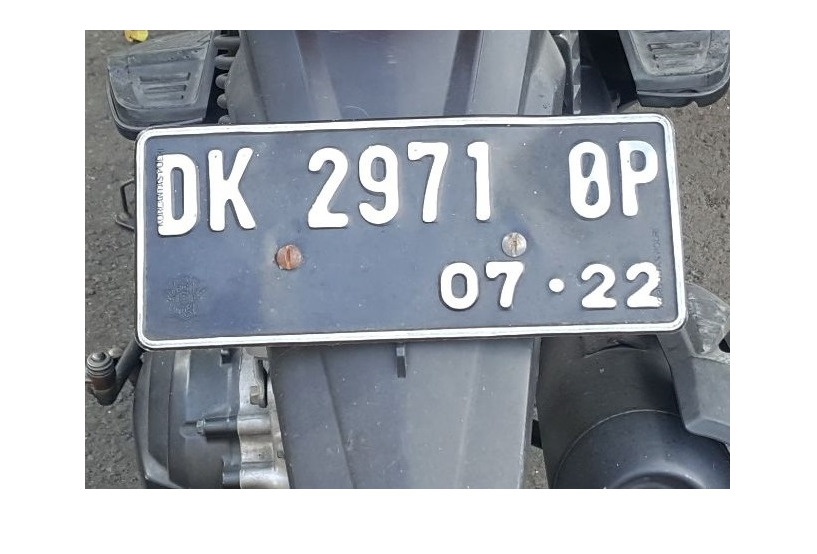

clear all;
I=imread('percobaan/2.jpg');    
figure,
imshow(I);

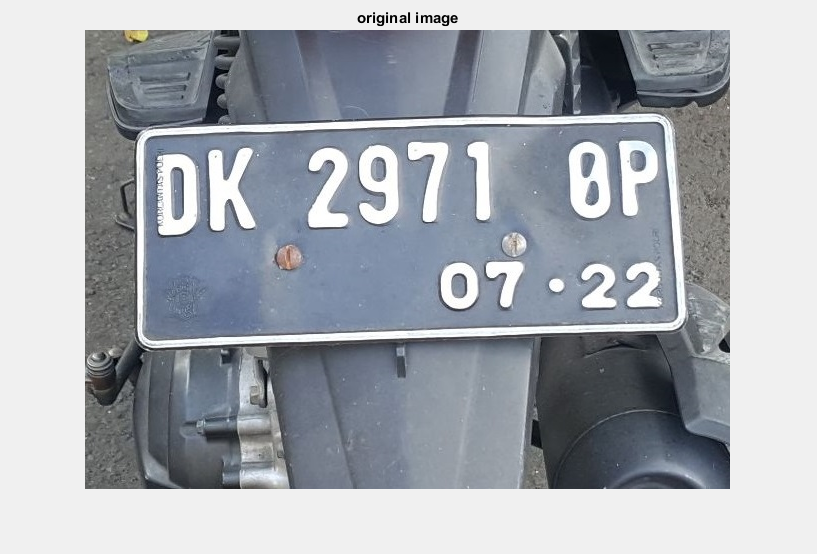

[J, rect] = imcrop(I);
title('original image');

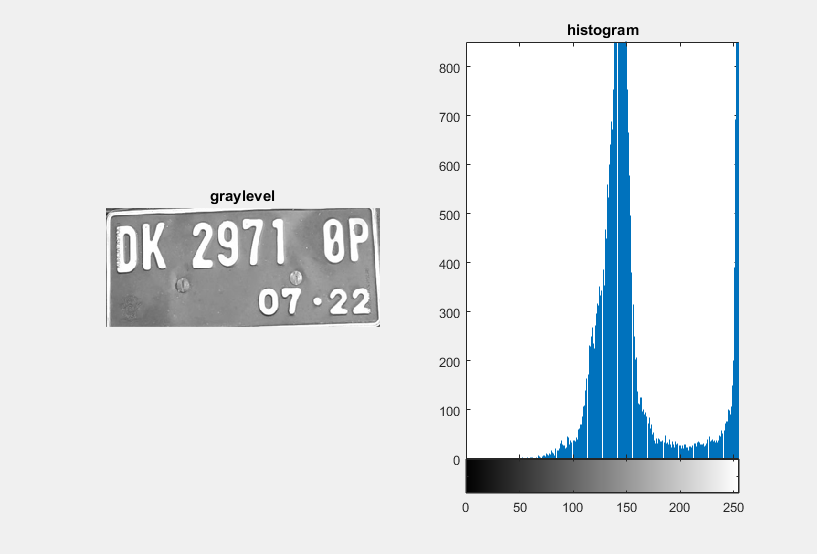

T = imresize(J, [130 300]);
Im1 = rgb2gray(T); 
figure(2),
subplot(1,2,1),
imshow(Im1); 
title('graylevel');
figure(2),
subplot(1,2,2),
imhist(Im1);
title('histogram');

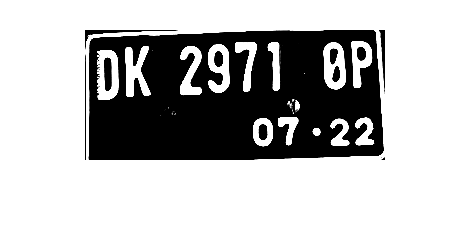

tes = imadjust(Im1,[0.7 0.8],[]);
figure,
imshow(tes);

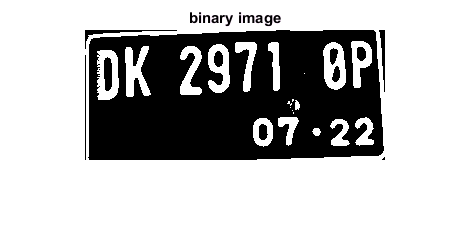

b = tes;
g_max = double(max(max(b)));
g_min = double(min(min(b)));
T = round(g_max-(g_max-g_min)/3);

d = double((b)>=T);

figure,

imshow(d),
title('binary image');

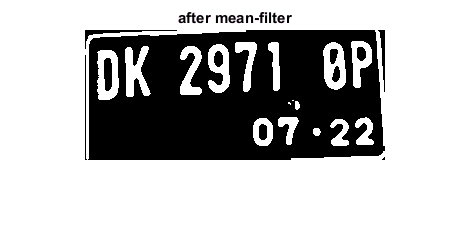

h = fspecial('average',3);
d = imbinarize(round(filter2(h,d)));
figure,
imshow(d),
title('after mean-filter');

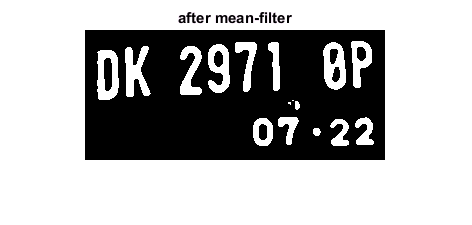

h = fspecial('average',3);
d = imclearborder(d, 4);
d = bwmorph(d,'close');
figure,
imshow(d),
title('after mean-filter');

se = strel('rectangle',[1,1]);
erosi = imerode(d,se);
figure,
imshow(erosi),
title('after mean-filter');

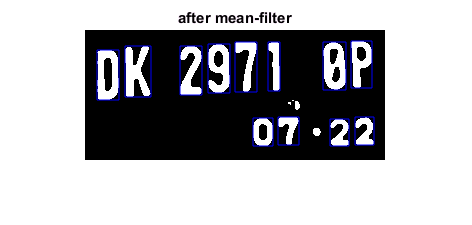

char = regionprops(erosi,'BoundingBox', 'Area', 'Eccentricity','Centroid');

figure;
imshow(erosi),
title('after mean-filter');
hold on ; %tetap mengaktifan figur citra biner di atas

for i=1:size(char,1)
    %tes(i) = char(i).Eccentricity;
    if (char(i).Area>=240)&&(char(i).Eccentricity>=0.600)&&(char(i).Eccentricity<=0.990)
    %cfix{i} = char(i).BoundingBox;
    rectangle('Position', char(i).BoundingBox,'edgecolor','blue');
    end
end

%rectangle('Position', char(33).BoundingBox,'edgecolor','red');

perlu clustering centroid dengan mencari centroid yg memiliki jarak sejajar

generationID = 2;
L=bwlabel(erosi,8);
siz=size(erosi);
n=max(L(:)); % number of objects
ObjCell=cell(n,1);
imageId = 1;
z = 1;
for i=1:n
      % Get the bb of the i-th object and offest by 2 pixels in all
      % directions
      char_i=ceil(char(i).BoundingBox);
      char_x=[char_i(1)-2 char_i(1)+char_i(3)+2];
      char_y=[char_i(2)-2 char_i(2)+char_i(4)+2];
      if char_x(1)<1, char_x(1)=1; end
      if char_y(1)<1, char_y(1)=1; end
      if char_x(2)>siz(2), char_x(2)=siz(2); end
      if char_y(2)>siz(1), char_y(2)=siz(1); end
      % Crop the object and write to ObjCell
      imchar=L==i;
      charfix{i}=imchar(char_y(1):char_y(2),char_x(1):char_x(2));
      
      if (char(i).Area>=350)&&(char(i).Eccentricity>=0.600)&&(char(i).Eccentricity<=0.990)
          img = imresize(charfix{i},[32, 16]);
          %img = bwmorph(img, 'thin', 'inf');
          imwrite(img, ['dataset/' num2str(generationID,'%d') '_' num2str(z,'%d') '.bmp'], 'bmp');
          imageId = imageId + 1;
          cf{i} = charfix{i};
          z = z +1;
      end
end

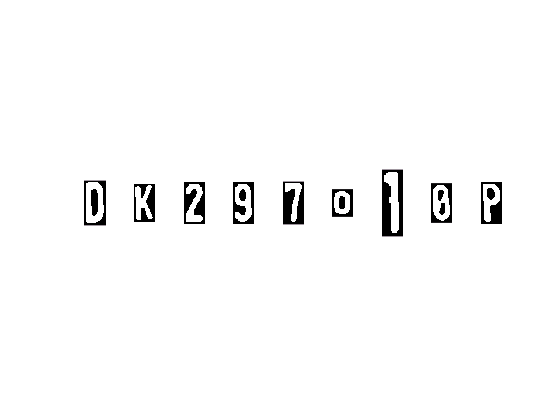

cf = cf(~cellfun(@isempty, cf));
p=length(cf);
figure
for j=1:p
    subplot(1,p,j)
    imshow(cf{j})
end

load templates
global templates

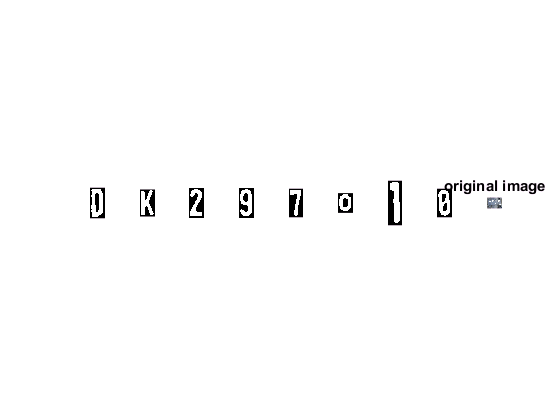

for flag2=1:p
    n2=imread(strcat('dataset\',num2str(generationID,'%d'),'_',num2str(flag2),'.bmp'));
    img_r=imresize(n2,[32 16]);
    letter=read_letter(img_r,36);
    result(flag2)=letter;
end
figure(11)
imshow(I);
title('original image');

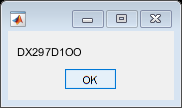

msgbox(result)